# Autoencoders for Wireless Communications

This example shows how to model an end-to-end communications system with an autoencoder to reliably transmit information bits over a wireless channel.

## Introduction

A traditional autoencoder is an unsupervised neural network that learns how to efficiently compress data, which is also called encoding. The autoencoder also learns how to reconstruct the data from the compressed representation such that the difference between the original data and the reconstructed data is minimal. 

Traditional wireless communication systems are designed to provide reliable data transfer over a channel that impairs the transmitted signals. These systems have multiple components such as channel coding, modulation, equalization, synchronization, etc. Each component is optimized independently based on mathematical models that are simplified to arrive at closed form expressions. On the contrary, an autoencoder jointly optimizes the transmitter and the receiver as a whole. This joint optimization has the potential of providing a better performance than the traditional systems [1],[2]. 

Traditional autoencoders are usually used to compress images, in other words remove redundancies in an image and reduce its dimension. A wireless communication system on the other hand uses channel coding and modulation techniques to add redundancy to the information bits. With this added redundancy, the system can recover the information bits that are impaired by the wireless channel. So, a wireless autoencoder actually adds redundancy and tries to minimize the number of errors in the received information for a given channel while learning to apply both channel coding and modulation in an unsupervised way. 

## Basic Autoencoder System

The following is the block diagram of a wireless autoencoder system. The encoder (transmitter) first maps $k$ information bits into a message s such that $s \in \{1,\dots,M\}$, where $M=2^k$. Then message s is mapped to n real number to create $\textbf{x} =f(s) \in \mathbb{R}^{n}$. The last layer of the encoder imposes constraints on $\textbf{x}$ to further restrict the encoded symbols. The following are possible such constraints and are implemented using the normalization layer:

- Energy constraint: $\Vert x \Vert^2_2\le n$

- Average power constraint: $\mathbb{E} \lbrack |x_i|^2 \rbrack \le 1, \forall i$

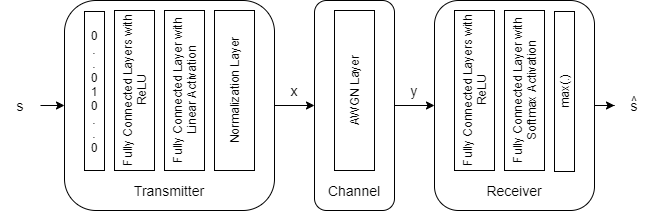

Define the communication rate of this system as $R=k/n$ [bits/channel use], where (*n*,*k*) means that the system sends one of $M=2^k$ messages using *n* channel uses. The channel impairs encoded (i.e. transmitted) symbols to generate $\textbf{y} \in \mathbb{R}^{n}$. The decoder (i.e. receiver) produces an estimate, $\hat{s}$, of the transmitted message, $s$. 

The input message is defined as a one-hot vector $\textbf{1}_s \in \mathbb{R}^M$, which is defined as a vector whose elements are all zeros except the $s^{\textrm{th}}$ one. The channel is additive white Gaussian noise (AWGN) that adds noise to achieve a given energy per data bit to noise power density ratio, $E_b/N_o$. 

The autoencoder maps $k$ data bits into $n$ channel uses, which results in an effective coding rate of $R=k/n$ data bits per channel use. Then, 2 channel uses are mapped into a symbol, which results in 2 channel uses per symbol. Map the channel uses per channel symbol value to the `BitsPerSymbol` parameter of the AWGN channel. 

Define a (7,4) autoencoder network with energy normalization and a training $E_b/N_o$ of 3 dB. In [1], authors showed that two fully connected layers for both the encoder (transmitter) and the decoder (receiver) provides the best results with minimal complexity. Input layer ([featureInputLayer](docid:nnet_ref#object_layer.featureinputlayer)) accepts a one-hot vector of length M. The encoder has two fully connected layers ([fullyConnectedLayer](docid:nnet_ref#mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d)). The first one has M inputs and M outputs and is followed by an ReLU layer ([reluLayer](docid:nnet_ref#mw_ca5427bd-5cdc-4a58-ba63-302c257d8222)). The second fully connected layer has M inputs and n outputs and is followed by the normalization layer ([helperAEWNormalizationLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWNormalizationLayer.m'))). The encoder layers are followed by the AWGN channel layer ([helperAEWAWGNLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAWGNLayer.m'))). The output of the channel is passed to the decoder layers. The first decoder layer is a fully connected layer that has n inputs and M outputs and is followed by an ReLU layer. The second fully connected layer has M inputs and M outputs and is followed by a softmax layer ([softmaxLayer](docid:nnet_ref#mw_a09d3c68-d062-4692-a950-9a7fea5c40c3)), which outputs the probability of each M symbols. The classification layer ([classificationLayer](docid:nnet_ref#bu5lho8)) outputs the most probable transmitted symbol from 0 to M-1. 

k = 8;    % number of input bits
M = 2^k;  % number of possible input symbols
n = 4;    % number of channel uses
EbNo = 13; % Eb/No in dB


%Initialize layer graph
wirelessAutoEncoder = [
    % Input layer
    sequenceInputLayer(1, 'Name', 'Input', 'Normalization', 'none')

    % Embedding layer (Using fully connected layer as embedding proxy)
    fullyConnectedLayer(256, 'Name', 'Embedding')
   

    % Encoder (Conv1D layers)
    convolution1dLayer(1, 256, 'Name', 'Conv1D_1')
    eluLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_2')
    eluLayer 
    convolution1dLayer(1, 64, 'Name', 'Conv1D_3')
    eluLayer 
    convolution1dLayer(1, 2 * n, 'Name', 'Conv1D_4')
    eluLayer 

    % Power Normalization Layer
    PowerConstraintLayer("Name", "PowerConstraint")

    % Normalization Layer (Custom implementation if needed)
    helperAEWNormalizationLayer("Method", "Energy", "Name", "Normalization")
   % normalize('norm', 2)
    SlidingWindow(13,"Name","SlidingWindow")
    % Stochastic Channel Layer
    StochasticChannelv3('Name', 'StochasticChannelv3')
    

    % Custom Noise Layer
    helperCustomizeNoiseLayer('Name', 'NoiseLayer')

    % SD_RNN Layer (Custom RNN implementation)
    %SDRNNLayer("Name","SDRNN")
    % Decoder (Conv1D layers)
    convolution1dLayer(1, 64, 'Name', 'Conv1D_Dec1')
    eluLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_Dec2')
    eluLayer
    convolution1dLayer(1, 256, 'Name', 'Conv1D_Dec3')
    eluLayer 

    % Output Layer
    fullyConnectedLayer(M, 'Name', 'Output')
    softmaxLayer('Name', 'Softmax')
    classificationLayer("Name","classoutput")
];
layerGraphModel = layerGraph(wirelessAutoEncoder);


train_dataset = repmat(0:M-1, 1, 64);
test_dataset = repmat(0:M-1, 1, 10);
val_dataset = repmat(0:M-1, 1, 10);
train_set = reshape(train_dataset, 1,[]);
test_set = reshape(test_dataset, 1, []);
val_set = reshape(val_dataset, 1, []);
train_set1 = train_set(randperm(length(train_set)));
test_set1 = test_set(randperm(length(test_set)));
val_set1= val_set(randperm(length(val_set)));

% Shuffle datasets
% train_set = num2cell(train_set1);
% val_set = num2cell(val_set1);
% test_set = num2cell(test_set1);

train_set = train_set1;
val_set = val_set1;
test_set = test_set1;

display(train_set)

train_set =    118    65   246    30   104   135    36   164   227    32    24   167    99   133    48    79   214   210    70    85   241   116    99   123   176    60   160    88   240   184   162   164   139    29    83   103    21   238   224    34     7   149    26   190   146   101   216   221   103   173


train_cell = categorical(train_set1);
test_cell = categorical(test_set1);
val_cell = categorical(val_set1);
display(train_set1)

train_set1 =    118    65   246    30   104   135    36   164   227    32    24   167    99   133    48    79   214   210    70    85   241   116    99   123   176    60   160    88   240   184   162   164   139    29    83   103    21   238   224    34     7   149    26   190   146   101   216   221   103   173


% Training options

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 6400, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'never', ...
    'ValidationData', {val_set, val_cell}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

padded_matrix = 20×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


output = 104×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


inputs = 104×1 single column vector
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


outputs = 476×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


padded_matrix = 20×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


output = 104×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


inputs = 104×1 single column vector
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


outputs = 476×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


padded_matrix = 20×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


output = 104×1 single column vector
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


inputs = 104×1 single column vector
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


outputs = 476×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


padded_matrix = 20×1×16384 single array
padded_matrix(:,:,1) =

         0
         0
         0
         0
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
         0
         0
         0
         0


padded_matrix(:,:,2) =

         0
         0
         0
         0
         0
         0
    0.4933
   -0.2696
    0.1063
   -0.3738
   -0.0814
    0.4211
    0.4886
   -0.3321
         0
         0
         0
         0
         0
         0


padded_matrix(:,:,3) =

         0
         0
         0
         0
         0
         0
    0.4992
   -0.1607
    0.1017
   -0.3659
   -0.0274
    0.4735
    0.4896
   -0.3407
         0
         0
         0
         0
         0
         0


padded_matrix(:,:,4) =

         0
         0
         0
         0
         0
         0
    0.5092
   -0.2768
    0.1297
   -0.2551
   -0.1240
    0.4450
    0.5077
   -0.3332
         0
         0
         0
         0


output = 104×1×16384 single array
output(:,:,1) =

         0
         0
         0
         0
         0
         0
    0.4973
   -0.2285
         0
         0
         0
         0
         0
    0.4973
   -0.2285
    0.0996
         0
         0
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
         0
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
         0
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
   

inputs = 104×1×16384 single array
inputs(:,:,1) =

         0
         0
         0
         0
         0
         0
    0.4973
   -0.2285
         0
         0
         0
         0
         0
    0.4973
   -0.2285
    0.0996
         0
         0
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
         0
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
         0
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
         0
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
    0.4973
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
   -0.2285
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
    0.0996
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
   -0.3774
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
         0
   -0.0521
    0.4447
    0.4900
   -0.3280
         0
         0
   

outputs = 476×1×16384 single array
outputs(:,:,1) =

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0379
         0
         0
         0
   -0.3239
         0
         0
         0
   -0.3569
         0
         0
         0
    0.2389
         0
         0
         0
    0.1665
         0
         0
         0
   -0.0725
         0
         0
         0
   -0.0557
         0
         0
         0
    0.1898
         0
         0
         0
   -0.3239
         0
         0
         0
   -0.3569
         0
         0
         0
    0.2389
         0
         0
         0
         0
         0
         0
         0
   -0.0725
         0
         0
         0
   -0.0557
         0
         0
         0
    0.1898
         0
         0
         0
   -0.3901
         0
         0
         0
   -0.3569
         0
         0
         0
    0.2389
         0
         0
 

dLdY = 476×1×16384 single array
dLdY(:,:,1) =

    0.0564
    0.0220
   -0.0426
   -0.0478
    0.0451
   -0.0087
   -0.0316
    0.0068
   -0.0016
    0.0178
   -0.0377
    0.0400
   -0.0216
    0.0321
   -0.0478
   -0.0210
   -0.0440
    0.0112
   -0.0400
    0.0132
   -0.0015
   -0.0370
   -0.0100
    0.0477
   -0.0073
   -0.0224
    0.0629
    0.0094
   -0.0520
   -0.0031
   -0.0004
    0.0157
   -0.0253
   -0.0502
   -0.0109
    0.0113
    0.0366
   -0.0208
   -0.0183
   -0.0431
   -0.0194
   -0.0142
    0.0746
   -0.0079
    0.0212
   -0.0128
    0.0301
    0.0820
   -0.0134
   -0.0095
   -0.0702
    0.0501
    0.0096
    0.0245
    0.0004
   -0.0139
   -0.0551
    0.0113
    0.0301
   -0.0133
   -0.0374
    0.0375
    0.0006
   -0.0273
   -0.0008
    0.0456
   -0.0453
   -0.0896
    0.0214
    0.0029
    0.0331
   -0.0124
   -0.0415
   -0.0319
   -0.0359
   -0.0235
   -0.0104
    0.0438
    0.0233
   -0.0019
    0.0421
    0.0131
   -0.0138
   -0.0347
   -0.0119
    0.0146
   -0.0

dLdY = 2×238×1×16384 single array
dLdY(:,:,1,1) =

    0.0564   -0.0426    0.0451   -0.0316   -0.0016   -0.0377   -0.0216   -0.0478   -0.0440   -0.0400   -0.0015   -0.0100   -0.0073    0.0629   -0.0520   -0.0004   -0.0253   -0.0109    0.0366   -0.0183   -0.0194    0.0746    0.0212    0.0301   -0.0134   -0.0702    0.0096    0.0004   -0.0551    0.0301   -0.0374    0.0006   -0.0008   -0.0453    0.0214    0.0331   -0.0415   -0.0359   -0.0104    0.0233    0.0421   -0.0138   -0.0119   -0.0335   -0.0134    0.0068   -0.0132    0.0114   -0.0133    0.0123    0.0008    0.0044    0.0651   -0.0122   -0.0201    0.0219    0.0112    0.0400   -0.0266    0.0503   -0.0601    0.0256   -0.0076   -0.0357   -0.0033    0.0268   -0.0051    0.0264   -0.0610    0.0003    0.0468    0.0326    0.0013   -0.0074   -0.0762    0.0526    0.0238   -0.0127    0.0249   -0.0285   -0.0055   -0.0110    0.0271    0.0233   -0.0120    0.0496    0.0111   -0.0661   -0.0383   -0.0005    0.0861    0.0237    0.0109   -0.0546   -0.054

real_downsampled = 1×208×1×16384 single array
real_downsampled(:,:,1,1) =

   -0.0004   -0.0253   -0.0109    0.0366   -0.0183   -0.0194    0.0746    0.0212    0.0301   -0.0134   -0.0702    0.0096    0.0004   -0.0551    0.0301   -0.0374    0.0006   -0.0008   -0.0453    0.0214    0.0331   -0.0415   -0.0359   -0.0104    0.0233    0.0421   -0.0138   -0.0119   -0.0335   -0.0134    0.0068   -0.0132    0.0114   -0.0133    0.0123    0.0008    0.0044    0.0651   -0.0122   -0.0201    0.0219    0.0112    0.0400   -0.0266    0.0503   -0.0601    0.0256   -0.0076   -0.0357   -0.0033    0.0268   -0.0051    0.0264   -0.0610    0.0003    0.0468    0.0326    0.0013   -0.0074   -0.0762    0.0526    0.0238   -0.0127    0.0249   -0.0285   -0.0055   -0.0110    0.0271    0.0233   -0.0120    0.0496    0.0111   -0.0661   -0.0383   -0.0005    0.0861    0.0237    0.0109   -0.0546   -0.0548   -0.0093   -0.0083   -0.0416   -0.0023    0.0347   -0.0328    0.0171   -0.0368    0.0042    0.0444    0.0429    0.0131   -0

real_downsampled = 4×52×16384 single array
real_downsampled(:,:,1) =

   -0.0004   -0.0183    0.0301    0.0004    0.0006    0.0331    0.0233   -0.0335    0.0114    0.0044    0.0219    0.0503   -0.0357    0.0264    0.0326    0.0526   -0.0285    0.0233   -0.0661    0.0237   -0.0093    0.0347    0.0042   -0.0153    0.0358    0.0559   -0.0339    0.0305   -0.0212   -0.0278   -0.0461   -0.0153    0.0410    0.0653    0.0581   -0.0142    0.0072    0.0228   -0.0034   -0.0389   -0.0098   -0.0272    0.0156    0.0481   -0.0165    0.0259   -0.0171   -0.0295   -0.0303   -0.0319   -0.0735    0.0010
   -0.0253   -0.0194   -0.0134   -0.0551   -0.0008   -0.0415    0.0421   -0.0134   -0.0133    0.0651    0.0112   -0.0601   -0.0033   -0.0610    0.0013    0.0238   -0.0055   -0.0120   -0.0383    0.0109   -0.0083   -0.0328    0.0444   -0.0008   -0.0586    0.0173   -0.0409   -0.0145    0.0036    0.0106   -0.0040    0.0181    0.0431    0.0628   -0.0260   -0.0568   -0.0447   -0.0142    0.0270   -0.0107   -0.061

real_downsampled = 52×4×16384 single array
real_downsampled(:,:,1) =

   -0.0004   -0.0253   -0.0109    0.0366
   -0.0183   -0.0194    0.0746    0.0212
    0.0301   -0.0134   -0.0702    0.0096
    0.0004   -0.0551    0.0301   -0.0374
    0.0006   -0.0008   -0.0453    0.0214
    0.0331   -0.0415   -0.0359   -0.0104
    0.0233    0.0421   -0.0138   -0.0119
   -0.0335   -0.0134    0.0068   -0.0132
    0.0114   -0.0133    0.0123    0.0008
    0.0044    0.0651   -0.0122   -0.0201
    0.0219    0.0112    0.0400   -0.0266
    0.0503   -0.0601    0.0256   -0.0076
   -0.0357   -0.0033    0.0268   -0.0051
    0.0264   -0.0610    0.0003    0.0468
    0.0326    0.0013   -0.0074   -0.0762
    0.0526    0.0238   -0.0127    0.0249
   -0.0285   -0.0055   -0.0110    0.0271
    0.0233   -0.0120    0.0496    0.0111
   -0.0661   -0.0383   -0.0005    0.0861
    0.0237    0.0109   -0.0546   -0.0548
   -0.0093   -0.0083   -0.0416   -0.0023
    0.0347   -0.0328    0.0171   -0.0368
    0.0042    0.0444    0.04

real_downsampled = 208×16384 single matrix
   -0.0004    0.0348   -0.0755    0.0324    0.0182   -0.0033   -0.0446   -0.0809   -0.0212    0.0369   -0.0116   -0.0045   -0.0074    0.0041    0.0148    0.0068    0.0170   -0.0092    0.0014    0.0373   -0.0212   -0.0018   -0.0074   -0.0812   -0.0364    0.0397    0.0024   -0.0397    0.0239    0.0313    0.0394   -0.0809   -0.0012   -0.0532   -0.0404   -0.0167   -0.0001    0.0174   -0.0409    0.0120    0.0512   -0.0090   -0.0431   -0.0964    0.0355    0.0258   -0.0427   -0.0178   -0.0167   -0.0451
   -0.0183   -0.0075    0.0254    0.0682   -0.0331   -0.0086    0.0115    0.0023    0.0524    0.0423   -0.0113    0.0301   -0.0271   -0.0118   -0.0247    0.0594   -0.0118    0.0051   -0.0363    0.0275    0.0371   -0.0171   -0.0271    0.0552    0.0353    0.0017   -0.0268   -0.0033   -0.0108    0.0365   -0.0240    0.0023   -0.0392    0.0359   -0.0229    0.0472   -0.0096    0.0255   -0.0505   -0.0818   -0.0558    0.0496    0.0645   -0.0224   -0.0538    0.

real = 52×16384 single matrix
   -0.0004    0.0348   -0.0755    0.0324    0.0182   -0.0033   -0.0446   -0.0809   -0.0212    0.0369   -0.0116   -0.0045   -0.0074    0.0041    0.0148    0.0068    0.0170   -0.0092    0.0014    0.0373   -0.0212   -0.0018   -0.0074   -0.0812   -0.0364    0.0397    0.0024   -0.0397    0.0239    0.0313    0.0394   -0.0809   -0.0012   -0.0532   -0.0404   -0.0167   -0.0001    0.0174   -0.0409    0.0120    0.0512   -0.0090   -0.0431   -0.0964    0.0355    0.0258   -0.0427   -0.0178   -0.0167   -0.0451
   -0.0183   -0.0075    0.0254    0.0682   -0.0331   -0.0086    0.0115    0.0023    0.0524    0.0423   -0.0113    0.0301   -0.0271   -0.0118   -0.0247    0.0594   -0.0118    0.0051   -0.0363    0.0275    0.0371   -0.0171   -0.0271    0.0552    0.0353    0.0017   -0.0268   -0.0033   -0.0108    0.0365   -0.0240    0.0023   -0.0392    0.0359   -0.0229    0.0472   -0.0096    0.0255   -0.0505   -0.0818   -0.0558    0.0496    0.0645   -0.0224   -0.0538    0.0330    0.005

out = 52×32768 single matrix
   -0.0004    0.0348   -0.0755    0.0324    0.0182   -0.0033   -0.0446   -0.0809   -0.0212    0.0369   -0.0116   -0.0045   -0.0074    0.0041    0.0148    0.0068    0.0170   -0.0092    0.0014    0.0373   -0.0212   -0.0018   -0.0074   -0.0812   -0.0364    0.0397    0.0024   -0.0397    0.0239    0.0313    0.0394   -0.0809   -0.0012   -0.0532   -0.0404   -0.0167   -0.0001    0.0174   -0.0409    0.0120    0.0512   -0.0090   -0.0431   -0.0964    0.0355    0.0258   -0.0427   -0.0178   -0.0167   -0.0451
   -0.0183   -0.0075    0.0254    0.0682   -0.0331   -0.0086    0.0115    0.0023    0.0524    0.0423   -0.0113    0.0301   -0.0271   -0.0118   -0.0247    0.0594   -0.0118    0.0051   -0.0363    0.0275    0.0371   -0.0171   -0.0271    0.0552    0.0353    0.0017   -0.0268   -0.0033   -0.0108    0.0365   -0.0240    0.0023   -0.0392    0.0359   -0.0229    0.0472   -0.0096    0.0255   -0.0505   -0.0818   -0.0558    0.0496    0.0645   -0.0224   -0.0538    0.0330    0.0052

out = 104×1×16384 single array
out(:,:,1) =

   -0.0004
   -0.0183
    0.0301
    0.0004
    0.0006
    0.0331
    0.0233
   -0.0335
    0.0114
    0.0044
    0.0219
    0.0503
   -0.0357
    0.0264
    0.0326
    0.0526
   -0.0285
    0.0233
   -0.0661
    0.0237
   -0.0093
    0.0347
    0.0042
   -0.0153
    0.0358
    0.0559
   -0.0339
    0.0305
   -0.0212
   -0.0278
   -0.0461
   -0.0153
    0.0410
    0.0653
    0.0581
   -0.0142
    0.0072
    0.0228
   -0.0034
   -0.0389
   -0.0098
   -0.0272
    0.0156
    0.0481
   -0.0165
    0.0259
   -0.0171
   -0.0295
   -0.0303
   -0.0319
   -0.0735
    0.0010
    0.0348
   -0.0075
    0.0048
   -0.0328
    0.0559
    0.0046
    0.0403
    0.0927
    0.0700
    0.0002
   -0.0021
   -0.0166
    0.0129
    0.0643
    0.0313
   -0.0509
   -0.0088
    0.0485
   -0.0173
   -0.0881
   -0.0356
   -0.0068
   -0.0496
    0.0288
   -0.0297
   -0.0480
    0.0377
   -0.0064
    0.0309
    0.1007
    0.0136
   -0.0200
   -0.0293
    0.0355
    0.015

dLdX = 104×1×16384 single array
dLdX(:,:,1) =

   -0.0004
   -0.0183
    0.0301
    0.0004
    0.0006
    0.0331
    0.0233
   -0.0335
    0.0114
    0.0044
    0.0219
    0.0503
   -0.0357
    0.0264
    0.0326
    0.0526
   -0.0285
    0.0233
   -0.0661
    0.0237
   -0.0093
    0.0347
    0.0042
   -0.0153
    0.0358
    0.0559
   -0.0339
    0.0305
   -0.0212
   -0.0278
   -0.0461
   -0.0153
    0.0410
    0.0653
    0.0581
   -0.0142
    0.0072
    0.0228
   -0.0034
   -0.0389
   -0.0098
   -0.0272
    0.0156
    0.0481
   -0.0165
    0.0259
   -0.0171
   -0.0295
   -0.0303
   -0.0319
   -0.0735
    0.0010
    0.0348
   -0.0075
    0.0048
   -0.0328
    0.0559
    0.0046
    0.0403
    0.0927
    0.0700
    0.0002
   -0.0021
   -0.0166
    0.0129
    0.0643
    0.0313
   -0.0509
   -0.0088
    0.0485
   -0.0173
   -0.0881
   -0.0356
   -0.0068
   -0.0496
    0.0288
   -0.0297
   -0.0480
    0.0377
   -0.0064
    0.0309
    0.1007
    0.0136
   -0.0200
   -0.0293
    0.0355
    0.0

grad = 104×1×16384 single array
grad(:,:,1) =

   -0.0004
   -0.0183
    0.0301
    0.0004
    0.0006
    0.0331
    0.0233
   -0.0335
    0.0114
    0.0044
    0.0219
    0.0503
   -0.0357
    0.0264
    0.0326
    0.0526
   -0.0285
    0.0233
   -0.0661
    0.0237
   -0.0093
    0.0347
    0.0042
   -0.0153
    0.0358
    0.0559
   -0.0339
    0.0305
   -0.0212
   -0.0278
   -0.0461
   -0.0153
    0.0410
    0.0653
    0.0581
   -0.0142
    0.0072
    0.0228
   -0.0034
   -0.0389
   -0.0098
   -0.0272
    0.0156
    0.0481
   -0.0165
    0.0259
   -0.0171
   -0.0295
   -0.0303
   -0.0319
   -0.0735
    0.0010
    0.0348
   -0.0075
    0.0048
   -0.0328
    0.0559
    0.0046
    0.0403
    0.0927
    0.0700
    0.0002
   -0.0021
   -0.0166
    0.0129
    0.0643
    0.0313
   -0.0509
   -0.0088
    0.0485
   -0.0173
   -0.0881
   -0.0356
   -0.0068
   -0.0496
    0.0288
   -0.0297
   -0.0480
    0.0377
   -0.0064
    0.0309
    0.1007
    0.0136
   -0.0200
   -0.0293
    0.0355
    0.0

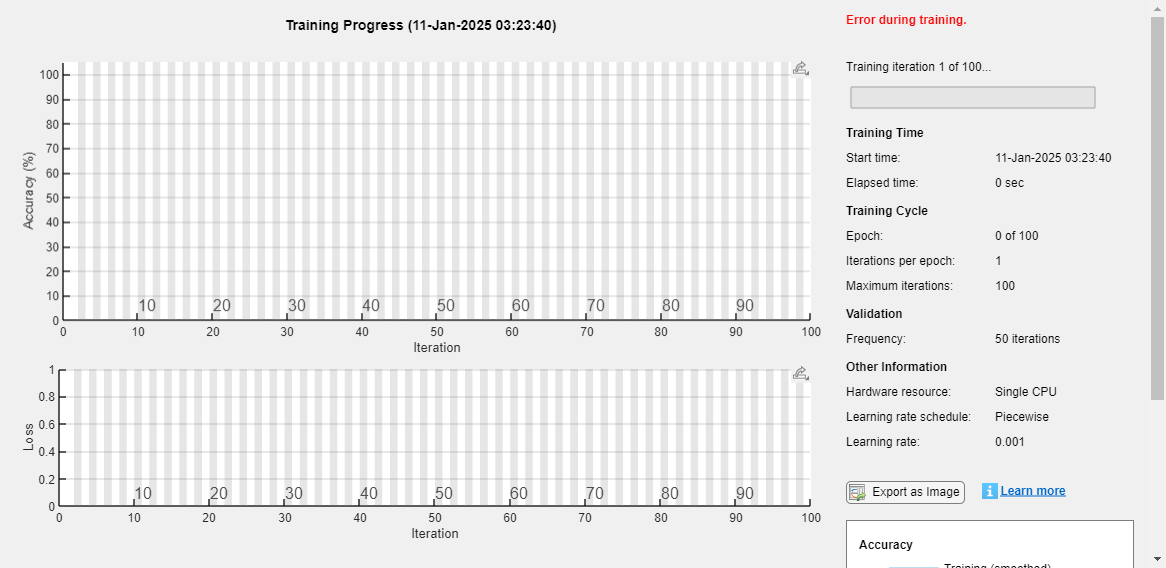

Error using trainNetwork
Error using the backward function in layer SlidingWindow. The function threw an error and could not be executed.

Caused by:
    Unrecognized function or variable 'rows'.

    Error in SlidingWindow/backward (line 53)
                gradients = grad(padsize:padsize+rows-1,:,:);

% Train the autoencoder
net = trainNetwork(train_set, train_cell, layerGraphModel, options);

% Predictions
predictions = predict(net, test_set);
display(test_set)
display(predictions)

% Define the feature extractor (fe) network
fe = [
    sequenceInputLayer(92, 'Name', 'feature_input')
    lstmLayer(16, 'OutputMode', 'sequence', 'Name', 'feature_extractor_lstm')
    flattenLayer('Name', 'feature_extractor_flatten')
    fullyConnectedLayer(8, 'Name', 'feature_extractor_output')
   
];

% Define the phase estimator (pe) network
pe = [
    sequenceInputLayer(92, 'Name', 'phase_input')
    lstmLayer(16, 'OutputMode', 'sequence', 'Name', 'phase_estimator_lstm')
    flattenLayer('Name', 'phase_estimator_flatten')
    fullyConnectedLayer(2, 'Name', 'phase_estimator_output')
];

% Define the offset estimator (oe) network
oe = [
    sequenceInputLayer(92, 'Name', 'offset_input')
    lstmLayer(16, 'OutputMode', 'sequence', 'Name', 'offset_estimator_lstm')
    lstmLayer(16, 'OutputMode', 'sequence', 'Name', 'offset_estimator_lstm1')
    lstmLayer(8, 'OutputMode', 'sequence', 'Name', 'offset_estimator_lstm2')
    flattenLayer('Name', 'offset_estimator_flatten')
    fullyConnectedLayer(1, 'Name', 'offset_estimator_output')
];
% Create dlnetwork objects for each sub-network
% Example input data (batch size of 1, 10 time steps, 92 features)
fe_input = dlarray(rand(92, 10,10),"CBT");
pe_input = dlarray(rand(92,10,10),"CBT");
oe_input = dlarray(rand(92, 10,10),"CBT");

feNet = dlnetwork(fe);
peNet = dlnetwork(pe);
oeNet = dlnetwork(oe);
display(fe_input)
% Forward pass through the feature extractor
fe_output = predict(feNet, fe_input);

% Forward pass through the phase estimator
pe_output = predict(peNet, pe_input);

% Forward pass through the offset estimator
oe_output = predict(oeNet, oe_input);

display(fe_input)
display(pe_input)
display(oe_input)

YPred = classify(net,test_set, ...
    MiniBatchSize=6400, ...
    SequenceLength="longest");
display(YPred)

accuracy = sum(YPred == test_cell) / numel(test_cell);
display(accuracy)
cm = confusionmat(test_cell, YPred);
accuracy = sum(diag(cm)) / sum(cm(:));
display(accuracy)

% Create and plot the confusion matrix
cm = confusionchart(test_cell, YPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';  % Normalize rows (optional)
cm.ColumnSummary = 'column-normalized';  % Normalize columns (optional)


layerNames = {net.Layers.Name};
layerOutput = {};
for i = 1:length(layerNames)
    layerName = layerNames{i};
    layerOutput(i) = activations(net, test_set, layerName);
    disp(['Outputs from layer ', layerName, ':']);
    disp(layerOutput(i));
end


options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 6400, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'never', ...
    'ValidationData', {val_set, val_cell}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

maxIter = 5;
done = false;
iterCnt = 0;
while ~done
  % Train the autoencoder network
  [trainedNet,info] = trainNetwork(train_set, train_cell, wirelessAutoEncoder, options);

  iterCnt = iterCnt + 1;
  % Check if the network converged or maximum iteration reached
  if (info.FinalValidationAccuracy > 80) || (iterCnt >= maxIter)
    done = true;
  end
end

% Generate random training data. Create one-hot input vectors and labels. 
M=256;
n=4;
k=8;
numTrainSymbols = 2500 * M;
numValidationSymbols = 100 * M;



d = randi([0 M-1],numTrainSymbols,1);
trainSymbols = zeros(numTrainSymbols,M);
trainSymbols(sub2ind([numTrainSymbols, M], ...
  (1:numTrainSymbols)',d+1)) = 1;
%trainSymbols = trainSymbols'
trainLabels = categorical(d);

d = randi([0 M-1],numValidationSymbols,1);
validationSymbols = zeros(numValidationSymbols,M);
validationSymbols(sub2ind([numValidationSymbols, M], ...
  (1:numValidationSymbols)',d+1)) = 1;
validationLabels = categorical(d);
%validationSymbols = validationSymbols'

%Initialize layer graph
wirelessAutoEncoder2 = [
    % Input layer
    %sequenceInputLayer(M, 'Name', "One-hot input", 'Normalization', 'none')
    featureInputLayer(M, 'Name', "One-hot input", 'Normalization', 'none')
    % Embedding layer (Using fully connected layer as embedding proxy)
    fullyConnectedLayer(256, 'Name', 'Embedding')
   

    % Encoder (Conv1D layers)
    fullyConnectedLayer(256,"Name","fc_1")
    %convolution1dLayer(1, 256, 'Name', 'Conv1D_1')
    eluLayer 
    %convolution1dLayer(1, 128, 'Name', 'Conv1D_2')
    fullyConnectedLayer(128,"Name","fc_2")
    eluLayer 
    fullyConnectedLayer(64,"Name","fc_3")
    %convolution1dLayer(1, 64, 'Name', 'Conv1D_3')
    eluLayer 
    %convolution1dLayer(1, 2 * n, 'Name', 'Conv1D_4')
    fullyConnectedLayer(2*n,"Name","fc_4")
    eluLayer 

    % Power Normalization Layer
    PowerConstraintLayer("Name", "PowerConstraint")

    % Normalization Layer (Custom implementation if needed)
    helperAEWNormalizationLayer("Method", "Energy", "Name", "Normalization")
   % normalize('norm', 2)
    
    % Stochastic Channel Layer
    %StochasticChannelv3('Name', 'StochasticChannelv3')
    

    % Custom Noise Layer
    helperCustomizeNoiseLayer('Name', 'NoiseLayer')

    % SD_RNN Layer (Custom RNN implementation)

    % Decoder (Conv1D layers)
    fullyConnectedLayer(64,"Name","fc_5")
    %convolution1dLayer(1, 64, 'Name', 'Conv1D_Dec1')
    eluLayer 
    %convolution1dLayer(1, 128, 'Name', 'Conv1D_Dec2')
    fullyConnectedLayer(128,"Name","fc_6")
    eluLayer
    fullyConnectedLayer(256,"Name","fc_7")
    %convolution1dLayer(1, 256, 'Name', 'Conv1D_Dec3')
    eluLayer 

    % Output Layer
    fullyConnectedLayer(M, 'Name', 'Output')
    softmaxLayer('Name', 'Softmax')
    classificationLayer("Name","classoutput")
];



options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 6400, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'never', ...
    'ValidationData', {validationSymbols, validationLabels}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

maxIter = 10;
done = false;
iterCnt = 0;
while ~done
  % Train the autoencoder network
  [trainedNet,info] = trainNetwork(trainSymbols,trainLabels,wirelessAutoEncoder2,options);

  iterCnt = iterCnt + 1;
  % Check if the network converged or maximum iteration reached
  if (info.FinalValidationAccuracy > 80) || (iterCnt >= maxIter)
    done = true;
  end
end

d = randi([0 M-1],numValidationSymbols,1);
testS = zeros(numValidationSymbols,M);
testS(sub2ind([numValidationSymbols, M], ...
  (1:numValidationSymbols)',d+1)) = 1;
testL = categorical(d);

predictions = predict(trainedNet, testS);
display(testS)
display(predictions)

YPred = classify(trainedNet,testS, ...
    MiniBatchSize=6400, ...
    SequenceLength="longest");
display(YPred)

accuracy = sum(YPred == testL) / numel(testL);
display(accuracy)
cm = confusionmat(test_cell, YPred);
accuracy = sum(diag(cm)) / sum(cm(:));
display(accuracy)

k = 8;    % number of input bits
M = 2^k;  % number of possible input symbols
n = 4;    % number of channel uses
EbNo = 13; % Eb/No in dB


%Initialize layer graph
wirelessAutoEncoder3 = [
    % Input layer
    sequenceInputLayer(1, 'Name', 'Input', 'Normalization', 'none')

    % Embedding layer (Using fully connected layer as embedding proxy)
    fullyConnectedLayer(256, 'Name', 'Embedding')
   

    % Encoder (Conv1D layers)
    fullyConnectedLayer( 256, 'Name', 'Conv1D_1')
    eluLayer 
    fullyConnectedLayer(128, 'Name', 'Conv1D_2')
    eluLayer 
    fullyConnectedLayer( 64, 'Name', 'Conv1D_3')
    eluLayer 
    fullyConnectedLayer(2 * n, 'Name', 'Conv1D_4')
    eluLayer 

    % Power Normalization Layer
    PowerConstraintLayer("Name", "PowerConstraint")

    % Normalization Layer (Custom implementation if needed)
    helperAEWNormalizationLayer("Method", "Energy", "Name", "Normalization")
   % normalize('norm', 2)
    
    % Stochastic Channel Layer
    StochasticChannelv3('Name', 'StochasticChannelv3')
    

    % Custom Noise Layer
    helperCustomizeNoiseLayer('Name', 'NoiseLayer')

    % SD_RNN Layer (Custom RNN implementation)

    % Decoder (Conv1D layers)
    fullyConnectedLayer( 64, 'Name', 'Conv1D_Dec1')
    eluLayer 
    fullyConnectedLayer(128, 'Name', 'Conv1D_Dec2')
    eluLayer
    fullyConnectedLayer(256, 'Name', 'Conv1D_Dec3')
    eluLayer 

    % Output Layer
    fullyConnectedLayer(M, 'Name', 'Output')
    softmaxLayer('Name', 'Softmax')
    classificationLayer("Name","classoutput")
];

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 6400, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'never', ...
    'ValidationData', {validationSymbols, validationLabels}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

numTrainSymbols = 2500 * M;
numValidationSymbols = 100 * M;

d = randi([0 M-1],numTrainSymbols,1);
trainSymbols = d;
%trainSymbols = trainSymbols'
trainLabels = categorical(d);

d = randi([0 M-1],numValidationSymbols,1);
validationSymbols = d;
validationLabels = categorical(d);
%validationSymbols = validationSymbols'

maxIter = 3;
done = false;
iterCnt = 0;
while ~done
  % Train the autoencoder network
  [trainedNet,info] = trainNetwork(trainSymbols,trainLabels,wirelessAutoEncoder3,options);

  iterCnt = iterCnt + 1;
  % Check if the network converged or maximum iteration reached
  if (info.FinalValidationAccuracy > 80) || (iterCnt >= maxIter)
    done = true;
  end
end

d = randi([0 M-1],numValidationSymbols,1);
testS = d;
testL = categorical(d);

predictions = predict(trainedNet, testS);
display(testS)
display(predictions)


YPred = classify(trainedNet,testS, ...
    MiniBatchSize=6400, ...
    SequenceLength="longest");
display(YPred)

accuracy = sum(YPred == testL) / numel(testL);
display(accuracy)
cm = confusionmat(test_cell, YPred);
accuracy = sum(diag(cm)) / sum(cm(:));
display(accuracy)

The [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function defines such a network based on the (n,k), normalization method and the $E_b/N_o$ values.

### Train Autoencoder

Run the [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function to train a (2,2) autoencoder with energy normalization. This function uses the [trainingOptions](docid:nnet_ref#bu59f0q) function to select 

- Adam (adaptive moment estimation) optimizer, 

- Initial learning rate of 0.08, 

- Maximum epochs of 10,

- Minibatch size of 100*M,

- Piecewise learning schedule with drop period of 5 and drop factor of 0.1.

Then, the [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function runs the [trainNetwork](docid:nnet_ref#bu6sn4c) function to train the autoencoder network with the selected options. Finally, this function separates the network into encoder and decoder parts. Encoder starts with the input layer and ends after the normalization layer. Decoder starts after the channel layer and ends with the classification layer. A feature input layer is added at the beginning of the decoder. 

Train the autoencoder with an $E_b/N_o$ value that is low enough to result in some errors but not too low such that the training algorithm cannot extract any useful information from the received symbols, y. Set $E_b/N_o$ to 3 dB. 

Use the plot object function of the trained network objects to show the layer graphs of the full autoencoder, the encoder network, i.e. the transmitter, and the decoder network, i.e. the receiver.  

## Simulate BLER Performance

Simulate the block error rate (BLER) performance of the (2,2) autoencoder. Set up simulation parameters.

Generate random integers in the [0 $M$-1] range that represents $k$ random information bits. Encode these information bits into complex symbols with [`helperAEWEncode`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWEncode.m')) function. `The helperAEWEncode` function runs the encoder part of the autoencoder then maps the real valued $\textbf{x}$ vector into a complex valued $\bf{x_c}$ vector such that the odd and even elements are mapped into the in-phase and the quadrature component of a complex symbol, respectively, where $\textbf{x}_c = \textbf{x}(1:2:end)+j\textbf{x}(2:2:end)$. In other words, treat the $\textbf{x}$ array as an interleaved complex array. 

Pass the complex symbols through an AWGN channel. Decode the channel impaired complex symbols with the [`helperAEWDecode`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWDecode.m')) function. The following code runs the simulation for each $E_b/N_o$ point for at least 10 block errors. To obtain more accurate results, increase minimum number of errors to at least 100. If [Parallel Computing Toolbox™](https://www.mathworks.com/products/parallel-computing.html) is installed and a license is available, uncomment the `parfor` line to run the simulations on a parallel pool. 

Plot the constellation learned by the autoencoder to send symbols through the AWGN channel together with the received constellation. For a (2,2) configuration, autoencoder learns a QPSK ($M=2^k=4$) constellation with a phase rotation. 

Bit error rate of QPSK is the same for both (8,8) and (2,2) cases. However, the BLER depends on the block length, $n$, and gets worse as $n$ increases as given by $BLER = 1-(1-BER)^n$. As expected, BLER performance of (8,8) QPSK is worse than the (2,2) QPSK system. The BLER performance of (2,2) autoencoder matches the BLER performance of (2,2) QPSK. On the other hand, (4,4) and (8,8) autoencoders optimize the channel coder and the constellation jointly to obtain a coding gain with respect to the corresponding uncoded QPSK systems. 

## Effect of Training Eb/No on BLER Performance

Train the (7,4) autoencoder with energy normalization under different $E_b/N_o$ values and compare the BLER performance. To extend the BLER curve, set simParams.EbNoVec to -2:0.5:8.

Plot the BLER performance together with theoretical upper bound for hard decision decoded Hamming (7,4) code and simulated BLER of maximum likelihood decoded (MLD) Hamming (7,4) code. The BLER performance of the (7,4) autoencoder gets closer to the Hamming (7,4) code with MLD as the training $E_b/N_o$ decreases from 10 dB to 1 dB, at which point it almost matches the MLD Hamming (7,4) code. 

## Conclusions and Further Exploration

The BLER results show that it is possible for autoencoders to learn joint coding and modulation schemes in an unsupervised way. It is even possible to train an autoencoder with R=1 to obtain a coding gain as compared to traditional methods. The example also shows the effect of hyperparameters such as $E_b/N_o$ on the BLER performance. 

The results are obtained using the following default settings for training and BLER simulations:

Vary these parameters to train different autoencoders and test their BLER performance. Experiment with different n, k, normalization and $E_b/N_o$ values. See the help for [helperAEWTrainWirelessAutoencoder.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')), [helperAEWPrepareAutoencoders.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPrepareAutoencoders.mlx')) and [helperAEWAutoencoderBLER.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAutoencoderBLER.m')) for more information.

### List of Helper Functions

- [helperAEWAWGNLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAWGNLayer.m'))

- [helperAEWNormalizationLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWNormalizationLayer.m'))

- [helperAEWEncode.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWEncode.m'))

- [helperAEWDecode.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWDecode.m'))

- [helperAEWTrainWirelessAutoencoder.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m'))

- [helperAEWPlotConstellation.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPlotConstellation.m'))

- [helperAEWPlotTrainingPerformance.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPlotTrainingPerformance.m'))

- [helperAEWAutoencoderBLER.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAutoencoderBLER.m'))

- [helperAEWPrepareAutoencoders.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPrepareAutoencoders.mlx'))

- [helperAEWSimulateBLER.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWSimulateBLER.mlx'))

## References

[1] T. O’Shea and J. Hoydis, "An Introduction to Deep Learning for the Physical Layer," in IEEE Transactions on Cognitive Communications and Networking, vol. 3, no. 4, pp. 563-575, Dec. 2017, doi: 10.1109/TCCN.2017.2758370.

[2] S. Dörner, S. Cammerer, J. Hoydis and S. t. Brink, "Deep Learning Based Communication Over the Air," in *IEEE Journal of Selected Topics in Signal Processing*, vol. 12, no. 1, pp. 132-143, Feb. 2018, doi: 10.1109/JSTSP.2017.2784180.

*Copyright 2020-2022 The MathWorks, Inc.*